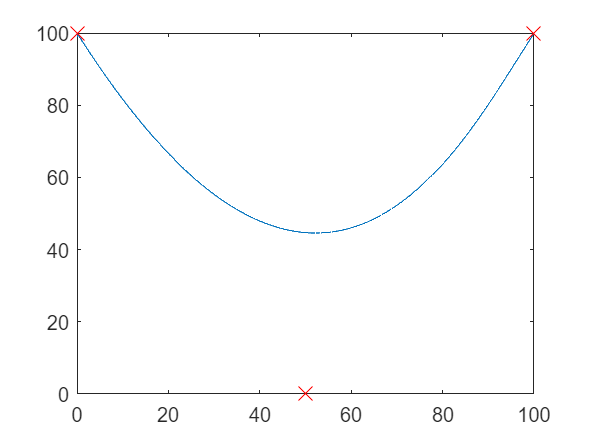

%24/02/2024 6th order b spline
%Control Points
P1 = [0, 100];
P2 = [50, 0];
P3 = [100, 100];
P4 = P3;
P5 = P4;
P6 = P5;
P7 = P6;
CP = [P1, P2, P3, P4, P5, P6, P7];
%Knot Vector
kn1 = 0;
kn2 = 0.01;
kn3 = 0.02;
kn4 = 0.03;
kn5 = 0.04;
kn6 = 0.05;
kn7 = 30;
kn8 = 59.95;
kn9 = 59.96;
kn10 = 59.97;
kn11 = 59.98;
kn12 = 59.99;
kn13 = 60;
knot = [kn1, kn2, kn3, kn4, kn5, kn6, kn7, kn8, kn9, kn10, kn11, kn12, kn13];
vpmin = kn5;
vpmax = kn8;
%Curve Parameters
pmin = 0;
pmax = 60;
pstep = 0.01;
stackx = [];
stacky = [];
for p = pmin:pstep:pmax
    if p >= vpmin
        if p<=vpmax
            [NKPx, NKPy] = NXK6(p, knot, CP);
            stackx = [stackx; NKPx];
            stacky = [stacky; NKPy];
        end
    end
end

%Display Control Points
CPx = [P1(1,1), P2(1,1), P3(1,1)];
CPy = [P1(1,2), P2(1,2), P3(1,2)];
%Path Curve
plot(stackx, stacky)
hold on
%Points
scatter(CPx, CPy, 100, "red", "X")
hold off

function [SumNPx, SumNPy] = NXK6(p, knot, CP)

    P1(1,1) = CP(1,1);
    P1(1,2) = CP(1,2);
    P2(1,1) = CP(1,3);
    P2(1,2) = CP(1,4);
    P3(1,1) = CP(1,5);
    P3(1,2) = CP(1,6);
    P4(1,1) = CP(1,7);
    P4(1,2) = CP(1,8);
    P5(1,1) = CP(1,9);
    P5(1,2) = CP(1,10);
    P6(1,1) = CP(1,11);
    P6(1,2) = CP(1,12);
    P7(1,1) = CP(1,13);
    P7(1,2) = CP(1,14);

    p1 = knot(1,1);
    p2 = knot(1,2);
    p3 = knot(1,3);
    p4 = knot(1,4);
    p5 = knot(1,5);
    p6 = knot(1,6);
    p7 = knot(1,7);
    p8 = knot(1,8);
    p9 = knot(1,9);
    p10 = knot(1,10);
    p11 = knot(1,11);
    p12 = knot(1,12);
    p13 = knot(1,13);

    if (p1<=p)
        if (p<p2)
            N1k1 = 1;
        else
            N1k1 = 0;
        end
    else
        N1k1 = 0;
    end
    if (p2<=p)
        if (p<p3)
            N2k1 = 1;
        else
            N2k1 = 0;
        end
    else
        N2k1 = 0;
    end
    if (p3<=p)
        if (p<p4)
            N3k1 = 1;
        else
            N3k1= 0;
        end
    else
        N3k1 = 0;
    end
    if (p4<=p)
        if (p<p5)
            N4k1 = 1;
        else
            N4k1 = 0;
        end
    else
        N4k1 = 0;
    end
    if (p5<=p)
        if (p<p6)
            N5k1 = 1;
        else
            N5k1 = 0;
        end
    else
        N5k1 = 0;
    end
    if (p6<=p)
        if (p<p7)
            N6k1 = 1;
        else
            N6k1 = 0;
        end
    else
        N6k1 = 0;
    end
    if (p7<=p)
        if (p<p8)
            N7k1 = 1;
        else
            N7k1 = 0;
        end
    else
        N7k1 = 0;
    end
    if (p8<=p)
        if (p<p9)
            N8k1 = 1;
        else
            N8k1 = 0;
        end
    else
        N8k1 = 0;
    end
    if (p9<=p)
        if (p<p10)
            N9k1 = 1;
        else
            N9k1 = 0;
        end
    else
        N9k1 = 0;
    end
    if (p10<=p)
        if (p<p11)
            N10k1 = 1;
        else
            N10k1 = 0;
        end
    else
        N10k1 = 0;
    end
    if (p11<=p)
        if (p<p12)
            N11k1 = 1;
        else
            N11k1 = 0;
        end
    else
        N11k1 = 0;
    end
    if (p12<=p)
        if (p<p13)
            N12k1 = 1;
        else
            N12k1 = 0;
        end
    else
        N12k1 = 0;
    end

    N1k2 = ((p-p1)/(p2-p1))*N1k1 + ((p3-p)/(p3-p2))*N2k1;
    N2k2 = ((p-p2)/(p3-p2))*N2k1 + ((p4-p)/(p4-p3))*N3k1;
    N3k2 = ((p-p3)/(p4-p3))*N3k1 + ((p5-p)/(p5-p4))*N4k1;
    N4k2 = ((p-p4)/(p5-p4))*N4k1 + ((p6-p)/(p6-p5))*N5k1;
    N5k2 = ((p-p5)/(p6-p5))*N5k1 + ((p7-p)/(p7-p6))*N6k1;
    N6k2 = ((p-p6)/(p7-p6))*N6k1 + ((p8-p)/(p8-p7))*N7k1;
    N7k2 = ((p-p7)/(p8-p7))*N7k1 + ((p9-p)/(p9-p8))*N8k1;
    N8k2 = ((p-p8)/(p9-p8))*N8k1 + ((p10-p)/(p10-p9))*N9k1;
    N9k2 = ((p-p9)/(p10-p9))*N9k1 + ((p11-p)/(p11-p10))*N10k1;
    N10k2 = ((p-p10)/(p11-p10))*N10k1 + ((p12-p)/(p12-p11))*N11k1;
    N11k2 = ((p-p11)/(p12-p11))*N11k1 + ((p13-p)/(p13-p12))*N12k1;

    N1k3 = ((p-p1)/(p3-p1))*N1k2 + ((p4-p)/(p4-p2))*N2k2;
    N2k3 = ((p-p2)/(p4-p2))*N2k2 + ((p5-p)/(p5-p3))*N3k2;
    N3k3 = ((p-p3)/(p5-p3))*N3k2 + ((p6-p)/(p6-p4))*N4k2;
    N4k3 = ((p-p4)/(p6-p4))*N4k2 + ((p7-p)/(p7-p5))*N5k2;
    N5k3 = ((p-p5)/(p7-p5))*N5k2 + ((p8-p)/(p8-p6))*N6k2;
    N6k3 = ((p-p6)/(p8-p6))*N6k2 + ((p9-p)/(p9-p7))*N7k2;
    N7k3 = ((p-p7)/(p9-p7))*N7k2 + ((p10-p)/(p10-p8))*N8k2;
    N8k3 = ((p-p8)/(p10-p8))*N8k2 + ((p11-p)/(p11-p9))*N9k2;
    N9k3 = ((p-p9)/(p11-p9))*N9k2 + ((p12-p)/(p12-p10))*N10k2;
    N10k3 = ((p-p10)/(p12-p10))*N10k2 + ((p13-p)/(p13-p11))*N11k2;

    N1k4 = ((p-p1)/(p4-p1))*N1k3 + ((p5-p)/(p5-p2))*N2k3;
    N2k4 = ((p-p2)/(p5-p2))*N2k3 + ((p6-p)/(p6-p3))*N3k3;
    N3k4 = ((p-p3)/(p6-p3))*N3k3 + ((p7-p)/(p7-p4))*N4k3;
    N4k4 = ((p-p4)/(p7-p4))*N4k3 + ((p8-p)/(p8-p5))*N5k3;
    N5k4 = ((p-p5)/(p8-p5))*N5k3 + ((p9-p)/(p9-p6))*N6k3;
    N6k4 = ((p-p6)/(p9-p6))*N6k3 + ((p10-p)/(p10-p7))*N7k3;
    N7k4 = ((p-p7)/(p10-p7))*N7k3 + ((p11-p)/(p11-p8))*N8k3;
    N8k4 = ((p-p8)/(p11-p8))*N8k3 + ((p12-p)/(p12-p9))*N9k3;
    N9k4 = ((p-p9)/(p12-p9))*N9k3 + ((p13-p)/(p13-p10))*N10k3;

    N1k5 = ((p-p1)/(p5-p1))*N1k4 + ((p6-p)/(p6-p2))*N2k4;
    N2k5 = ((p-p2)/(p6-p2))*N2k4 + ((p7-p)/(p7-p3))*N3k4;
    N3k5 = ((p-p3)/(p7-p3))*N3k4 + ((p8-p)/(p8-p4))*N4k4;
    N4k5 = ((p-p4)/(p8-p4))*N4k4 + ((p9-p)/(p9-p5))*N5k4;
    N5k5 = ((p-p5)/(p9-p5))*N5k4 + ((p10-p)/(p10-p6))*N6k4;
    N6k5 = ((p-p6)/(p10-p6))*N6k4 + ((p11-p)/(p11-p7))*N7k4;
    N7k5 = ((p-p7)/(p11-p7))*N7k4 + ((p12-p)/(p12-p8))*N8k4;
    N8k5 = ((p-p8)/(p12-p8))*N8k4 + ((p13-p)/(p13-p9))*N9k4;

    N1k6 = ((p-p1)/(p6-p1))*N1k5 + ((p7-p)/(p7-p2))*N2k5;
    N2k6 = ((p-p2)/(p7-p2))*N2k5 + ((p8-p)/(p8-p3))*N3k5;
    N3k6 = ((p-p3)/(p8-p3))*N3k5 + ((p9-p)/(p9-p4))*N4k5;
    N4k6 = ((p-p4)/(p9-p4))*N4k5 + ((p10-p)/(p10-p5))*N5k5;
    N5k6 = ((p-p5)/(p10-p5))*N5k5 + ((p11-p)/(p11-p6))*N6k5;
    N6k6 = ((p-p6)/(p11-p6))*N6k5 + ((p12-p)/(p12-p7))*N7k5;
    N7k6 = ((p-p7)/(p12-p7))*N7k5 + ((p13-p)/(p13-p8))*N8k5;

    SumNPx = N1k6*P1(1,1) + N2k6*P2(1,1) + N3k6*P3(1,1) + N4k6*P4(1,1) + N5k6*P5(1,1) + N6k6*P6(1,1) + N7k6*P7(1,1);
    SumNPy = N1k6*P1(1,2) + N2k6*P2(1,2) + N3k6*P3(1,2) + N4k6*P4(1,2) + N5k6*P5(1,2) + N6k6*P6(1,2) + N7k6*P7(1,2);
end